# **Taller 1**

Cargamos el sistema

load("modelo_lin.mat")

Empieza la búsqueda del error numérico

linmodel

linmodel =
 
  A = 
                 phi       theta         psi           p           q           r           u           v           w          Xe
   phi    -1.455e-24   3.676e-24           0           1  -9.266e-05     0.05385           0           0           0           0
   theta  -3.665e-24           0           0           0           1    0.001721           0           0           0           0
   psi    -2.706e-23   1.976e-25           0           0   -0.001723       1.001           0           0           0           0
   p               0           0           0      -16.14     -0.1393       3.377     0.06442      -2.831    0.003345   2.699e-09
   q               0           0           0   3.493e-24      -15.85       1.243       1.042  -6.238e-22      -7.427   7.059e-21
   r               0           0           0      0.5154     -0.7116      -2.783     0.00587       1.706   0.0003079   2.459e-10
   u               0      -9.791           0           0      -0.871  -1.655e

Eje desacoplado longitudinal - Pitch

longmod

longmod =
 
  A = 
                   u           w           q       theta          Ze       omega
   u         -0.5961      0.8011      -0.871      -9.791   5.053e-05     0.01263
   w         -0.7454      -7.581       15.72     -0.5272  -0.0009384           0
   q           1.042      -7.427      -15.85           0  -8.001e-16    -0.01318
   theta           0           0           1           0           0           0
   Ze       -0.05377      0.9986           0         -17           0           0
   omega       135.8       7.315           0           0    -0.08268      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711         0
   q        -134.1         0
   theta         0         0
   Ze            0         0
   omega         0      2506
 
  C = 
                   u           w           q       theta          Ze       omega
   V          0.9986     0.05377           0           0           0           0
   alpha   -0.003163     0.0587

Ejes acoplados laterales - Row - Yaw

latmod

latmod =
 
  A = 
                 v           p           r         phi         psi
   v        -0.875      0.8751      -16.82       9.791           0
   p        -2.831      -16.14       3.377           0           0
   r         1.706      0.5154      -2.783           0           0
   phi           0           1     0.05385  -1.455e-24           0
   psi           0           0       1.001  -2.706e-23           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r   

**Análisis de los sistemas:**

Polos y ceros del sistema completo

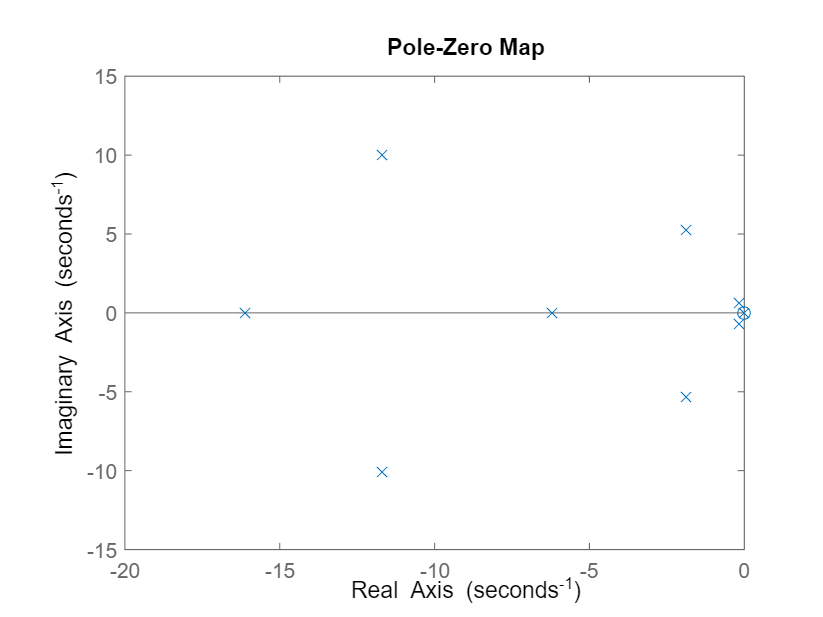

%[plinm, zlinnm] =
pzmap(linmodel)

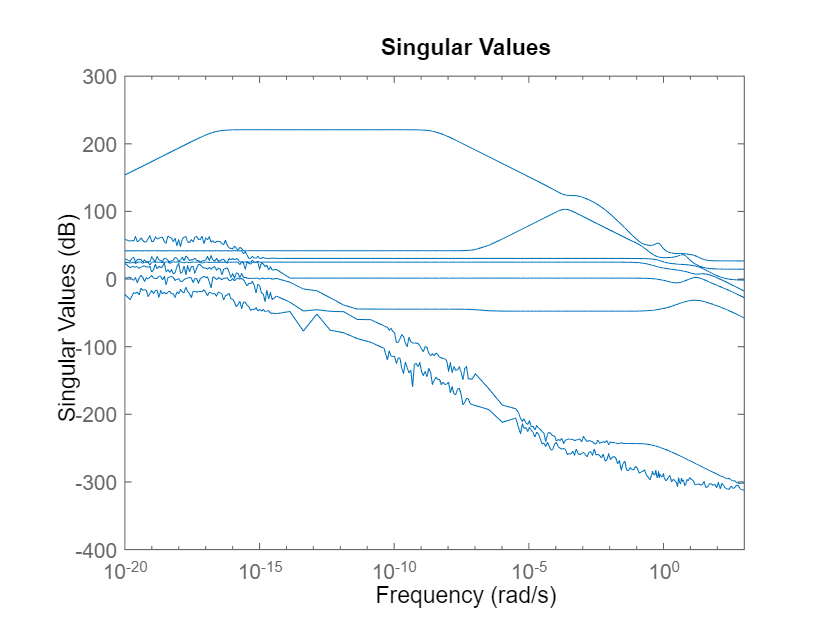

sigma(linmodel)

Polos y Zeros del  modelo longitudinal

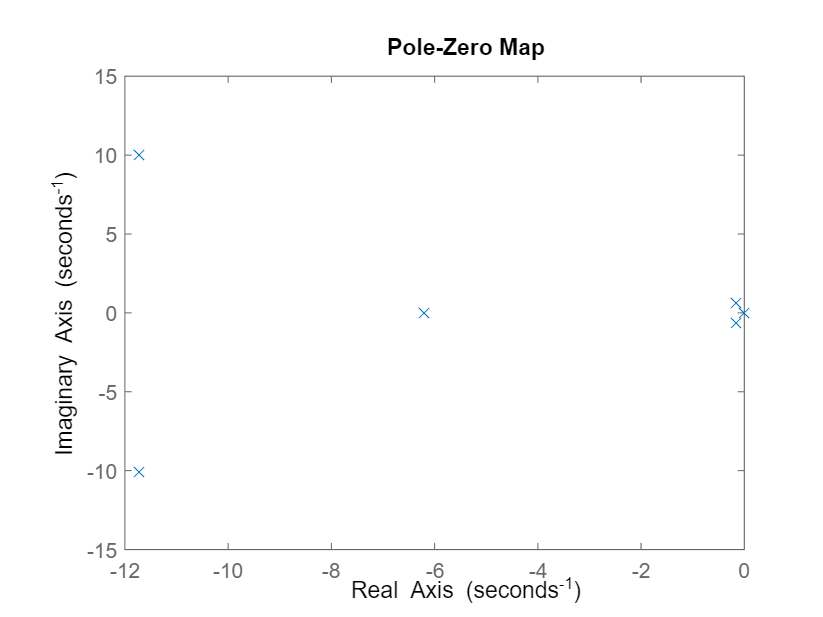

%[plongm, zlongnm] = 
pzmap(longmod)

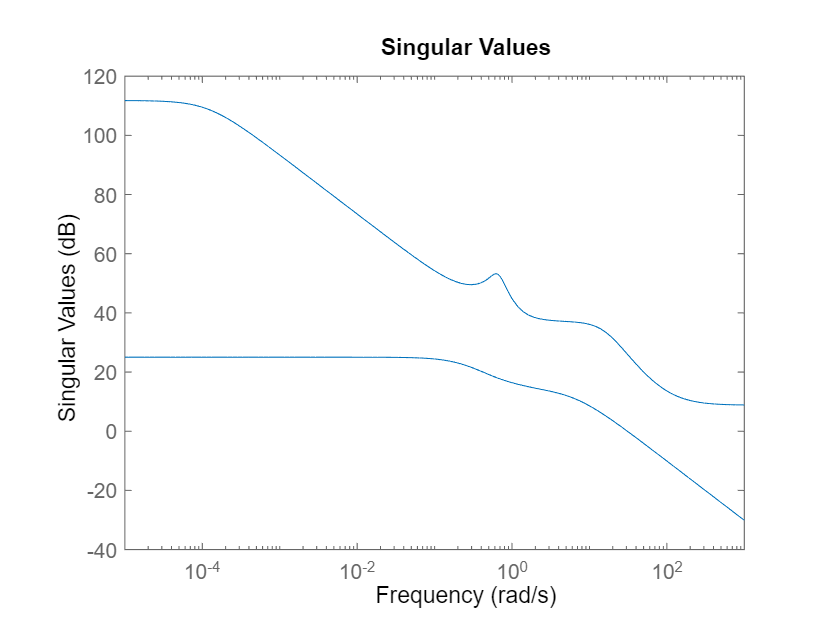

sigma(longmod)

Polos y Zeros del  modelo lateral

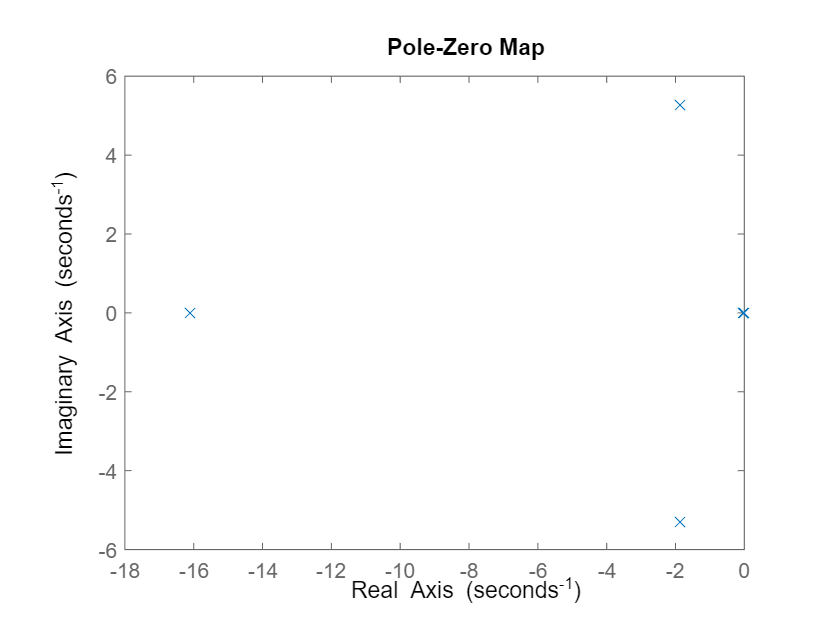

%[platm, zlatm] = 
pzmap(latmod)

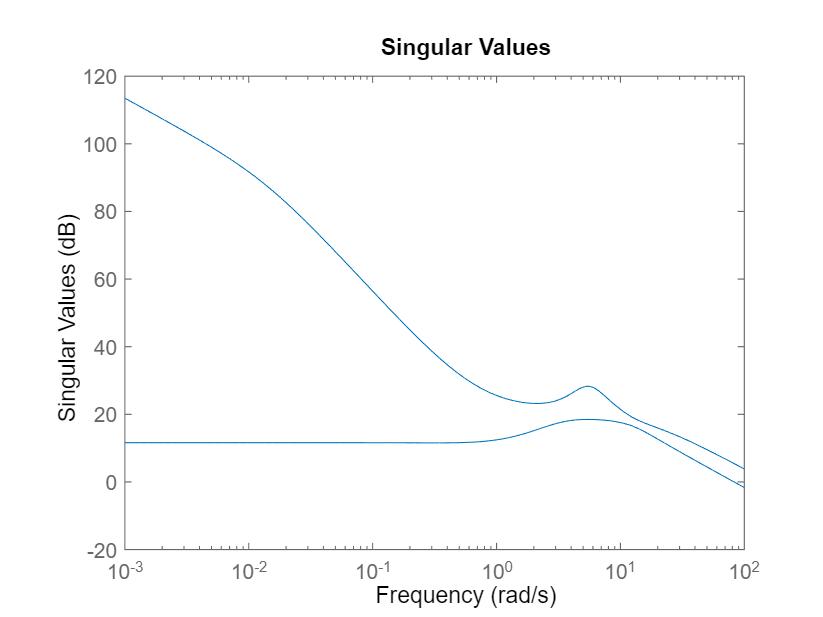

sigma(latmod)

**Polos con la función del profe**

[https://controlsystemsacademy.com/0024/0024.html](https://controlsystemsacademy.com/0024/0024.html) 

En ese link explican apropiadamente cual es la constante de tiempo, que basicamente corresponde al inverso de la parte real del polo, la frecuencia corresponde a la magnitud del polo; finalmente el damping corresponde al coseno de 180 - angulo del polo

Modelo lineal completo

damp(linmodel)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.20e-15                -1.00e+00       1.20e-15        -8.34e+14    
 -3.26e-09                 1.00e+00       3.26e-09         3.06e+08    
  3.08e-04                -1.00e+00       3.08e-04        -3.24e+03    
 -6.06e-04                 1.00e+00       6.06e-04         1.65e+03    
 -5.89e-03                 1.00e+00       5.89e-03         1.70e+02    
 -1.64e-01 + 6.42e-01i     2.48e-01       6.63e-01         6.10e+00    
 -1.64e-01 - 6.42e-01i     2.48e-01       6.63e-01         6.10e+00    
 -1.86e+00 + 5.28e+00i     3.32e-01       5.59e+00         5.38e-01    
 -1.86e+00 - 5.28e+00i     3.32e-01       5.59e+00         5.38e-01    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e

Modelo longitudinal

damp(longmod)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.60e-01 + 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -1.60e-01 - 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e-01    
 -1.17e+01 + 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    
 -1.17e+01 - 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    


Modelo lateral

damp(latmod)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -1.39e-02                 1.00e+00       1.39e-02         7.22e+01    
 -1.84e+00 + 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.84e+00 - 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    
